# Reading files

clear
path = "DataCleaned/Me/";
helloFile=dir('DataCleaned/Me/hello*.*');
hruFile=dir('DataCleaned/Me/hru*.*');
welcomeFile=dir('DataCleaned/Me/welcome*.*');
nice2meetuFile=dir('DataCleaned/Me/nice2meetu*.*');
%C:/Me
% helloFile=dir('C:/Me/hello*.*');
% hruFile=dir('C:/Me/hru*.*');
% welcomeFile=dir('C:/Me/welcome*.*');
% nice2meetuFile=dir('C:/Me/nice2meetu*.*');


# Plotting data

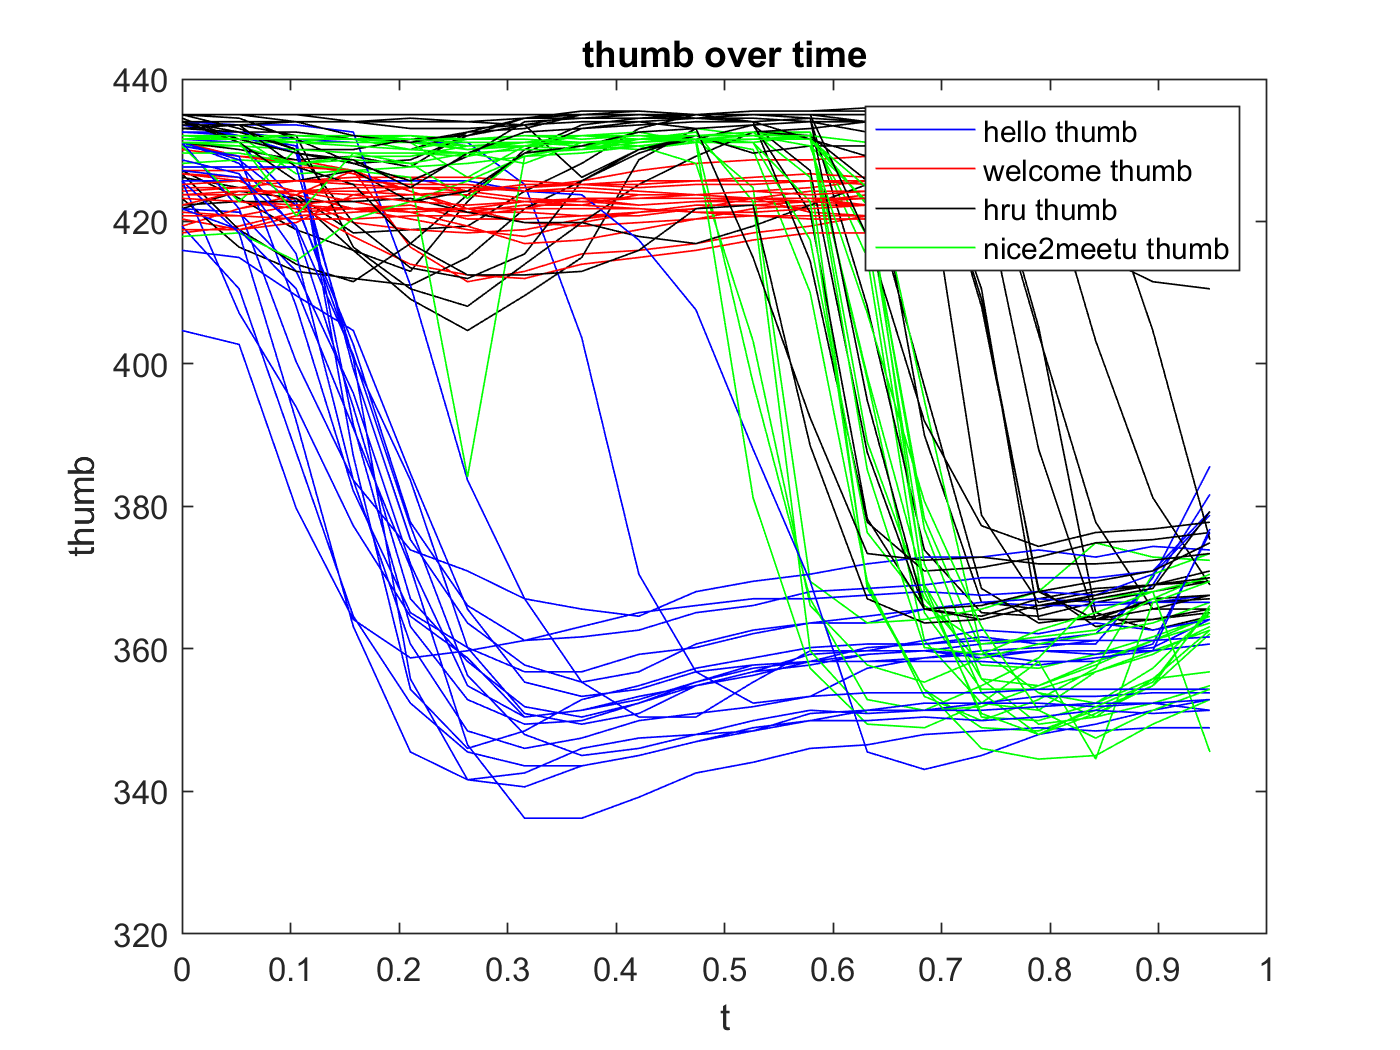

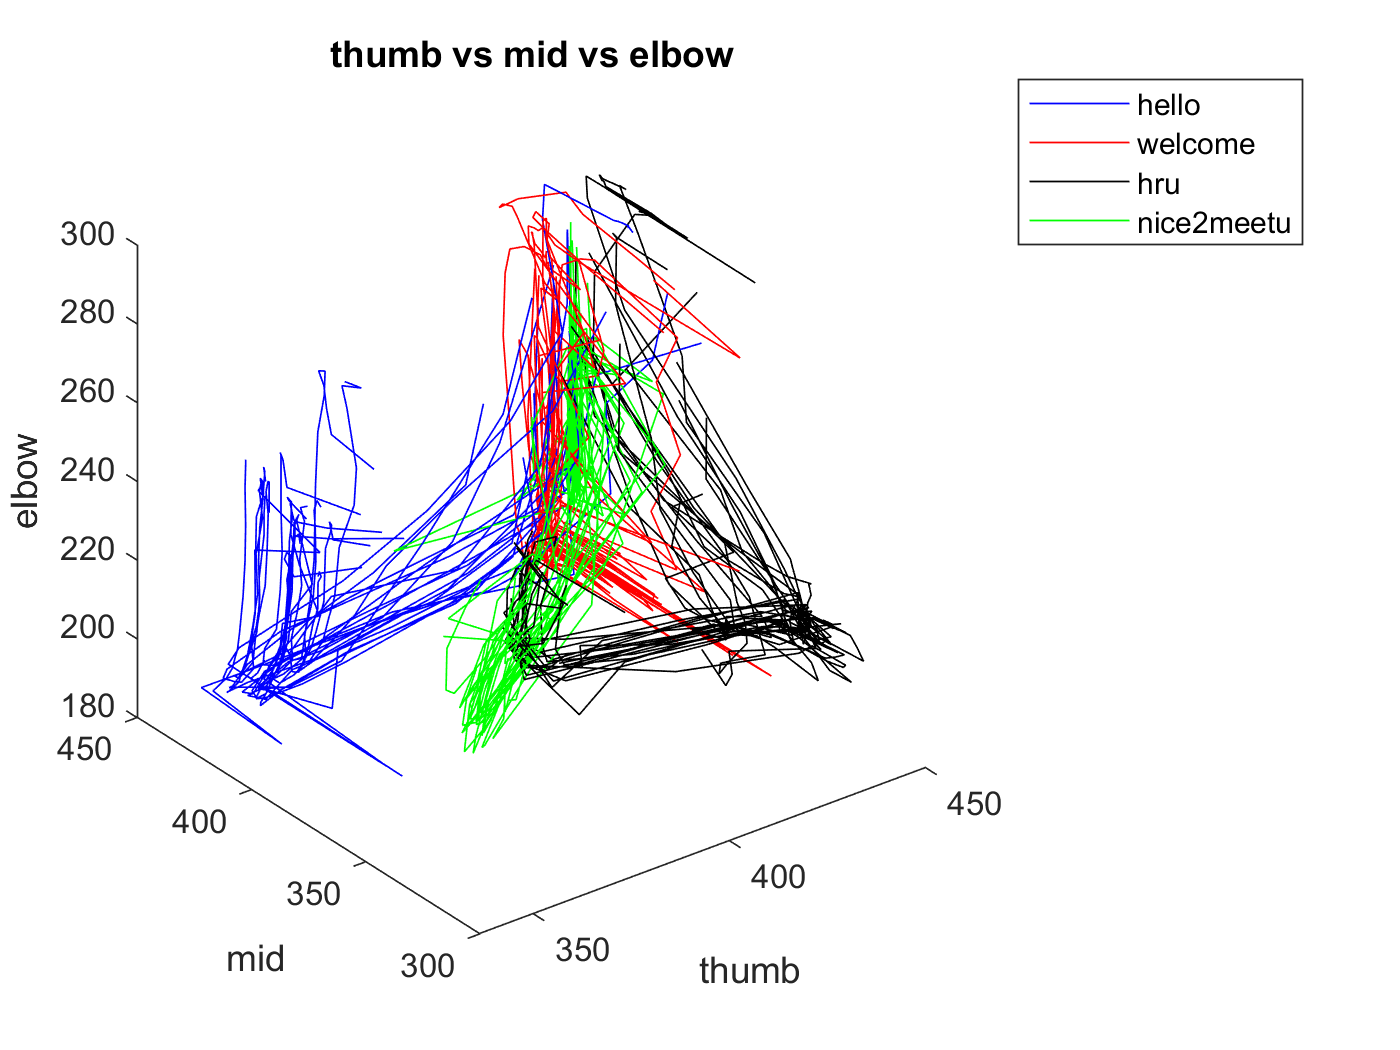

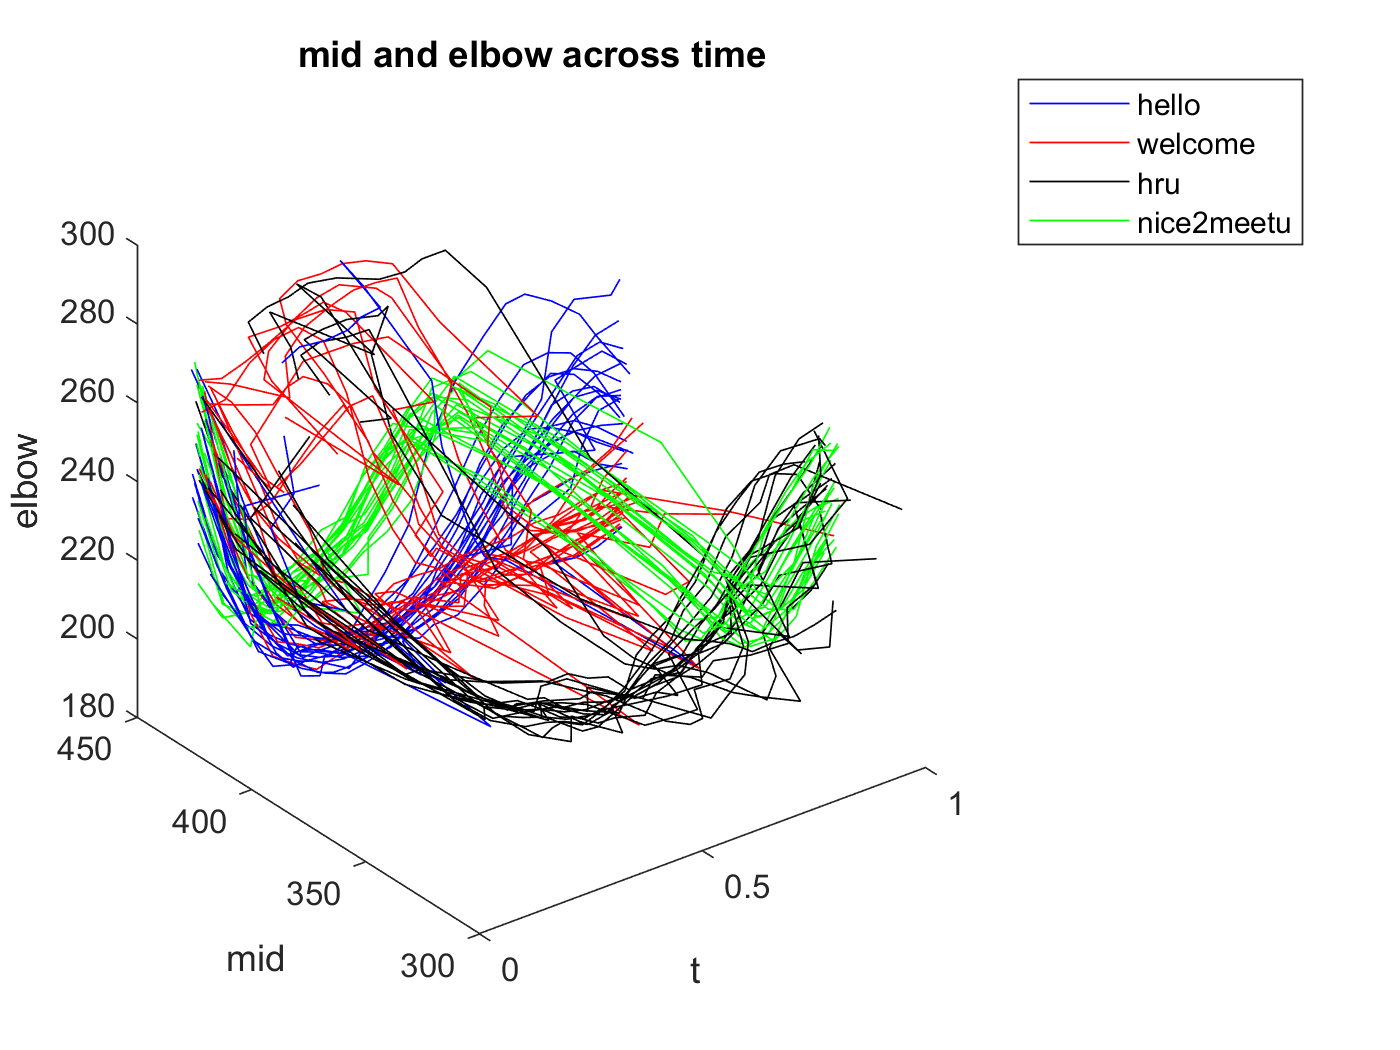

close all
dt = 1/19;
t = 0:dt:1-dt;
for i=10:30 %1 & 2 are empty
    
   hello_name= strcat(path, helloFile(i).name);
   hello = readtable(hello_name);
   welcome_name= strcat(path, welcomeFile(i).name);
   welcome = readtable(welcome_name);
   hru_name= strcat(path, hruFile(i).name);
   hru = readtable(hru_name);
   nice2meetu_name= strcat(path, nice2meetuFile(i).name);
   nice2meetu = readtable(nice2meetu_name);
   
   figure(1)
   plot(t, hello.thumb, 'b', t, welcome.thumb, 'r')
   hold on
   plot(t, hru.thumb, 'k', t, nice2meetu.thumb, 'g')

   xlabel('t')
   ylabel('thumb')
   title('thumb over time')
   legend('hello thumb', 'welcome thumb', 'hru thumb', 'nice2meetu thumb')
   
   figure(2)
   plot3(hello.thumb, hello.mid, hello.elbow,'b', welcome.thumb, welcome.mid, welcome.elbow, 'r')
   hold on
   plot3(hru.thumb, hru.mid, hru.elbow, 'k', nice2meetu.thumb, nice2meetu.mid, nice2meetu.elbow, 'g')

   xlabel('thumb')
   ylabel('mid')
   zlabel('elbow')
   title('thumb vs mid vs elbow')
   legend('hello', 'welcome', 'hru', 'nice2meetu')
   
   figure(3)
   plot3(t, hello.mid, hello.elbow,'Color','b')
   hold on
   plot3(t, welcome.mid, welcome.elbow,'Color','r')
   plot3(t, hru.mid, hru.elbow,'Color','k')
   plot3(t, nice2meetu.mid, nice2meetu.elbow,'Color','g')



   xlabel('t')
   ylabel('mid')
   zlabel('elbow')
   title('mid and elbow across time')
   legend('hello', 'welcome', 'hru', 'nice2meetu')
    
end